# Kinematyka robota mobilnego

clear all; clc; close all;

## Parametry symulacji

dt=0.1; % krok całkowania
ts=15; % czas symulacji
t=0:dt:ts; %time span



## Warunki początkowe

x0=0.5;
y0=0.5;

psi0=0;

eta0=[x0;y0;psi0];

eta(: , 1) = eta0; % przypisanie pierwszej kolumnie 
                   % trzech warunków początkowych w kolejnych wierszach

## Start pętli

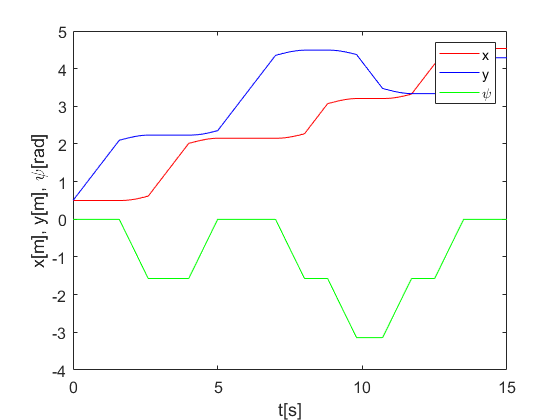

for i=1:length(t)
    time = i*dt;

    psi = eta(3,i); %aktualna orientacja w rad
    %Jakobian macierzy:
    J_psi=[cos(psi),-sin(psi),0;
           sin(psi),cos(psi),0;
           0,0,1];

    % Warunki dla poruszania się

    if(time <= 1.6) %do góry
        u = 0; 
        v = 1; 
        r = 0;
        
    elseif(time > 1.6) && (time <= 2.6) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2;
    elseif(time > 2.6) && (time <= 4) %do przodu
        u = 0; 
        v = 1; 
        r = 0;   
    elseif(time > 4) && (time <= 5) %zakręt w lewo
        u = 0; 
        v = 0.2; 
        r = pi/2;  
    elseif(time > 5) && (time <= 7) %do przodu
        u = 0; 
        v = 1; 
        r = 0; 
    elseif(time > 7) && (time <= 8) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2; 
    elseif(time > 8) && (time <= 8.8) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 8.8) && (time <= 9.8) %zakręt w prawo
        u = 0; 
        v = 0.2; 
        r = -pi/2; 
    elseif(time > 9.8) && (time <= 10.75) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 10.75) && (time <= 11.75) %zakręt w lewo
        u = 0; 
        v = 0.2; 
        r = pi/2;
    elseif(time > 11.75) && (time <= 12.5) %do przodu
        u = 0; 
        v = 1; 
        r = 0;
    elseif(time > 12.5) && (time <= 13.5) %zakręt w lewo
        u = 0; 
        v = 0.6; 
        r = pi/2;
    
    elseif(time > 13.5) && (time <= 14.2) %do przodu
        u = 0; 
        v = 1; 
        r = 0;    
    elseif(time > 14.2) && (time <= 15)
        u = 0; 
        v = 0; 
        r = 0; 
    end

       
       zeta(:,i)=[u;v;r];
       
       eta_dot(:,i) = J_psi*zeta(:,i);
       
       eta(:,i+1) = eta(:,i)+dt*eta_dot(:,i); % metoda Eulera
end

% %% Wydruk funkcji
 
 figure
 plot(t, eta(1,1:i),'r-');
 hold on
 
 plot(t, eta(2,1:i),'b-');
 hold on
 
 plot(t, eta(3,1:i),'g-');
 
 xlabel('t[s]');
 ylabel('x[m], y[m], \psi[rad]');
 legend('x','y','\psi'), set(gca,'fontsize',12);

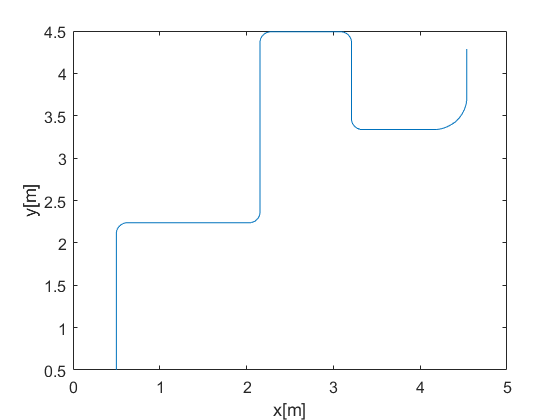

 
 figure
 plot(eta(1,1:i), eta(2,1:i));
xlabel('x[m]');
ylabel('y[m]');
set(gca,'fontsize',12);




%% ============================

## ETAP 2: DYNAMIKA – SZKIELET DO UZUPEŁNIENIA

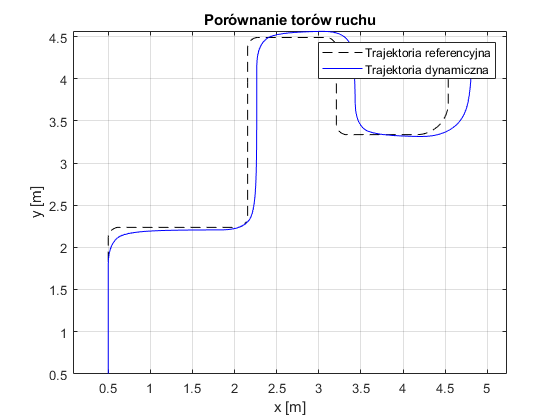


%% ============================

% Parametry fizyczne robota
m = 10;
J = 2;
kv = 0;
kr = 0;

% Parametry regulatora P
Kp_v = 2;
Kp_r = 3;

% Inicjalizacja zmiennych
v = 0;
r = 0;
eta_dyn(:,1) = eta(:,1);

for i = 1:length(t)
    psi = eta_dyn(3,i);
    J_psi = [cos(psi), -sin(psi), 0;
             sin(psi),  cos(psi), 0;
                  0,         0,  1];

    v_ref = zeta(2,i);
    r_ref = zeta(3,i);

    % === TODO: zaimplementuj regulator P ===
    F_cmd = Kp_v * (v_ref - v) * m;
    T_cmd = Kp_r * (r_ref - r) * J;

    % === TODO: dodaj opory ruchu (kv, kr) ===
    F = F_cmd - kv * v;
    T = T_cmd - kr * r;

    % === TODO: oblicz przyspieszenia i integruj ===
    a_v = F / m;
    a_r = T / J;

    v = v + a_v * dt;
    r = r + a_r * dt;

    zeta_dyn(:,i) = [0; v; r];
    eta_dot_dyn = J_psi * zeta_dyn(:,i);
    %eta_dyn(:,i+1) = eta_dyn(:,i) + dt * eta_dot;
    eta_dyn(:,i+1) = eta_dyn(:,i) + eta_dot_dyn * dt;
end

%% Porównanie trajektorii
figure;
plot(eta(1,:), eta(2,:), 'k--'); hold on;
plot(eta_dyn(1,:), eta_dyn(2,:), 'b');
legend('Trajektoria referencyjna','Trajektoria dynamiczna');
title('Porównanie torów ruchu');
xlabel('x [m]'); ylabel('y [m]'); axis equal; grid on;

## Animacja ruchu robota mobilnego

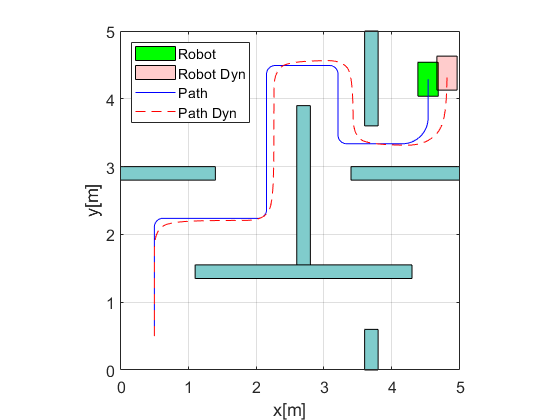

%% Animacja ruchu robota mobilnego z przeszkodami
l=0.3; % długość platformy
w=0.5; % szerokość platformy

% Współrzędne opisujące kształt platformy robota
mr_co=[-l/2,l/2,l/2,-l/2,-l/2;
        -w/2,-w/2,w/2,w/2,-w/2];

% Współrzędne ścian
walls = [
    0, 2.8, 1.4, 0.2;
    3.6, 0, 0.2, 0.6;
    3.4, 2.8, 1.6, 0.2;
    3.6, 3.6, 0.2, 1.4;
    1.1, 1.35,  3.2, 0.2;
    2.6, 1.55,  0.2, 2.35;
];

figure
for i=1:length(t) % początek animacji

    psi = eta(3,i);
    R_psi = [cos(psi), -sin(psi);
             sin(psi), cos(psi)]; % macierz rotacji
    v_pos = R_psi * mr_co;

    % Rysowanie robota
    fill(v_pos(1,:)+eta(1,i), v_pos(2,:)+eta(2,i),'g'); % robot
    hold on;
    fill(v_pos(1,:)+eta_dyn(1,i), v_pos(2,:)+eta_dyn(2,i),'r', 'FaceAlpha',0.2); % robot
    hold on, grid on;
    
    %ściany
    for j = 1:size(walls, 1)
        % Każda ściana
        rectangle('Position', [walls(j,1), walls(j,2), walls(j,3), walls(j,4)], ...
                  'FaceColor', [0.5, 0.8, 0.8], 'EdgeColor', 'k', 'LineWidth', 0.5);
    end

    axis([0 5 0 5]), axis square
    plot(eta(1,1:i), eta(2,1:i), 'b-'); % ścieżka ruchu
    plot(eta_dyn(1,1:i), eta_dyn(2,1:i), 'r--') % ścieżka ruchu dynamicznego

    legend('Robot','Robot Dyn', 'Path', 'Path Dyn' ,'Location','northwest'), set(gca,'fontsize',12)
    xlabel('x[m]'); ylabel('y[m]');
    pause(0.1);
    hold off
end % koniec animacji